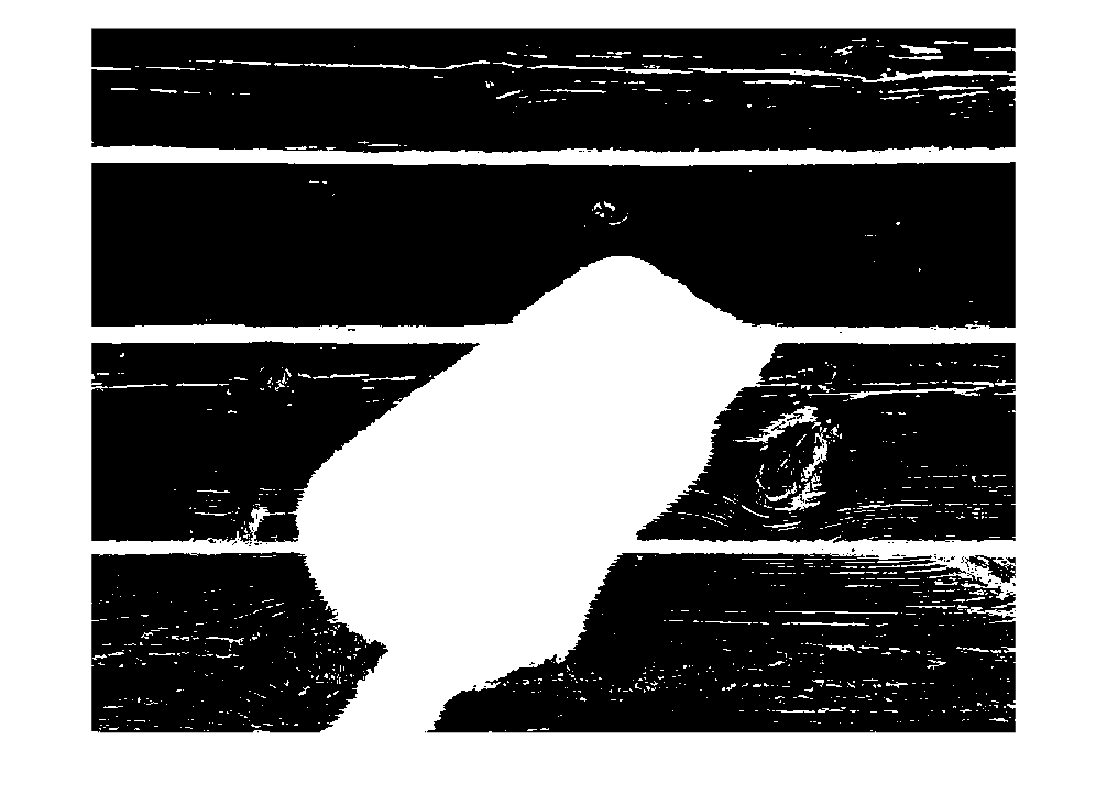

or_img = imread('CS270-Digitial-Image-Processing\project\dataset\shadow/_MG_6147.jpg');

y_cb_cr_img = rgb2ycbcr(or_img);
h_s_v_img = rgb2hsv(or_img);

% YCbCr Model
y_channel = y_cb_cr_img(:, :, 1); 
y_mean = mean(y_channel(:));
y_std = std(double(y_channel(:)));
threshold = y_mean - 1/10*y_std;
y_shadow_mask = y_channel < threshold;
imshow(y_shadow_mask,[]);

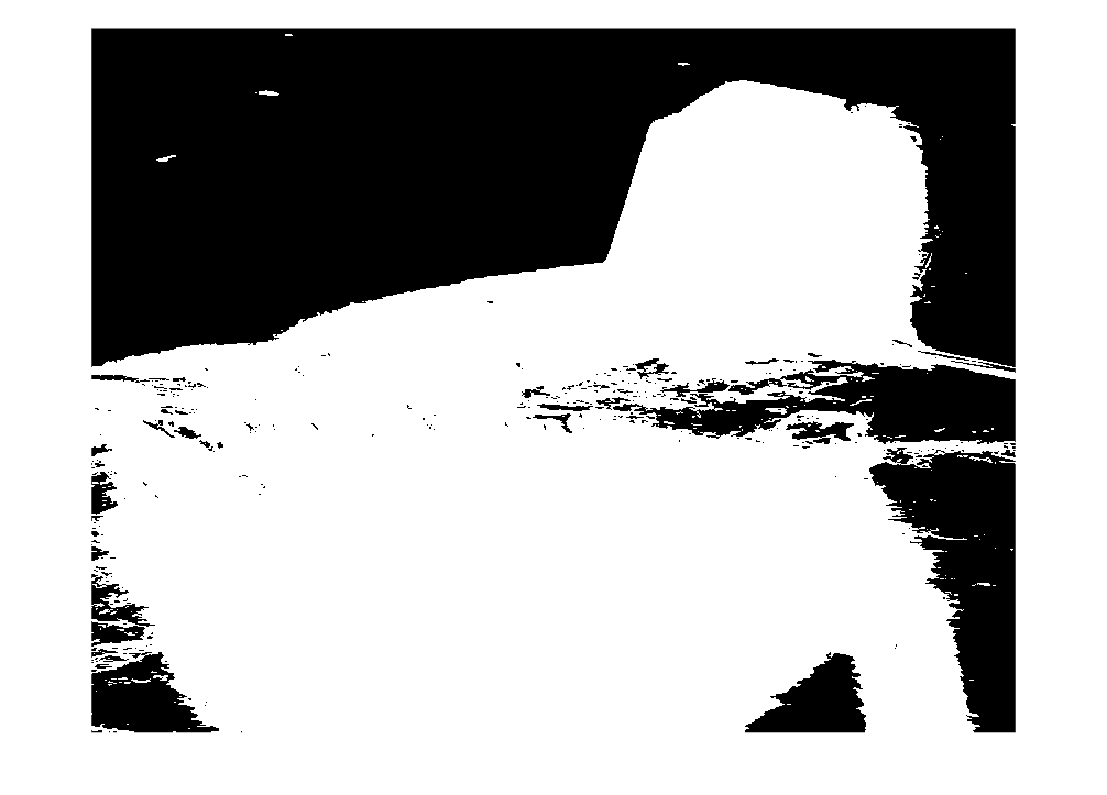

% HSV Model
v_channel = h_s_v_img(:,:,3);
v_mean = mean(v_channel(:));
v_shadow_mask = v_channel < v_mean;
imshow(v_shadow_mask,[]);

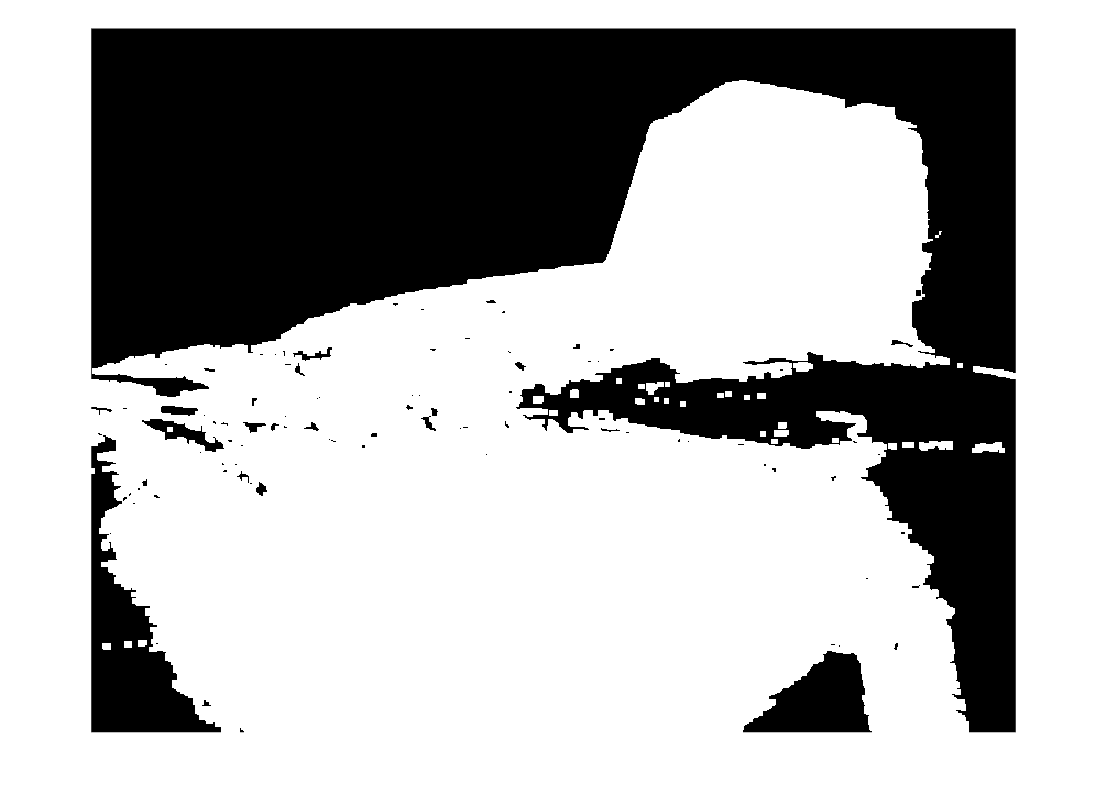

%
se = strel('disk', 3);  
open_mask = imopen(y_shadow_mask, se);  % 开运算去除噪声
closed_mask = imclose(v_shadow_mask,se);
initial_mask = closed_mask & open_mask;
imshow(initial_mask,[]);

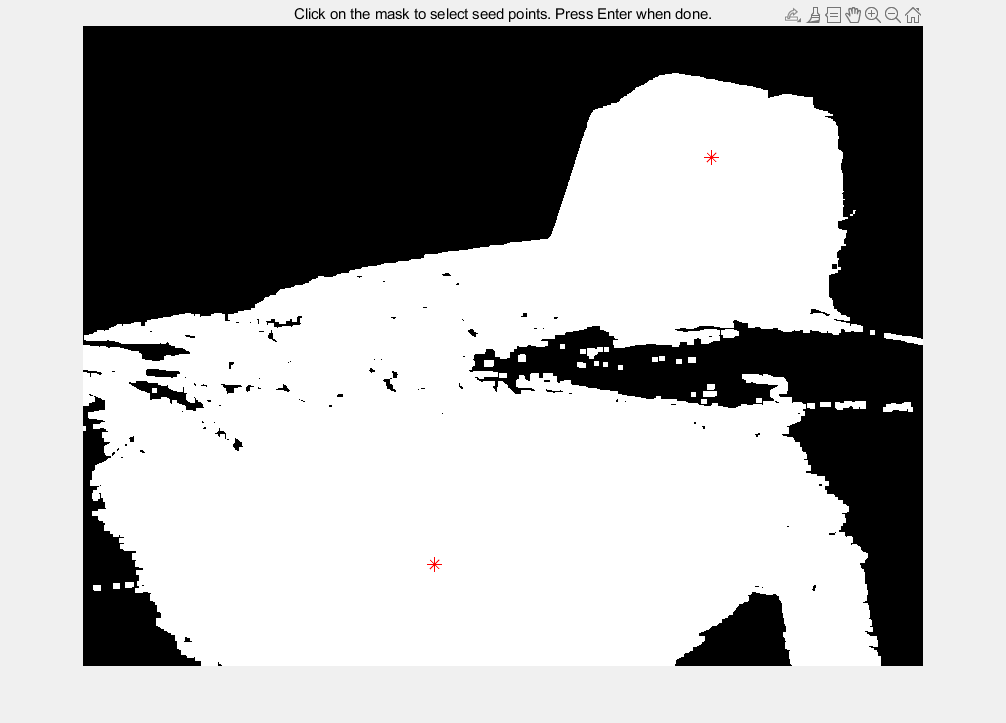


% 显示初始掩码并提示用户选择点
figure;
imshow(initial_mask, []);
title('Click on the mask to select seed points. Press Enter when done.');
hold on;

% 交互式获取用户点击的基础点
[x, y] = ginput();  % 用户点击坐标
x = round(x);       % 转换为整数索引
y = round(y);

% 验证用户选择的点是否在图像范围内
[h, w] = size(initial_mask);
valid_points = (x > 0 & x <= w) & (y > 0 & y <= h);  % 有效点
x = x(valid_points);
y = y(valid_points);

% 在图像上标记用户选择的基础点
plot(x, y, 'r*', 'MarkerSize', 10);

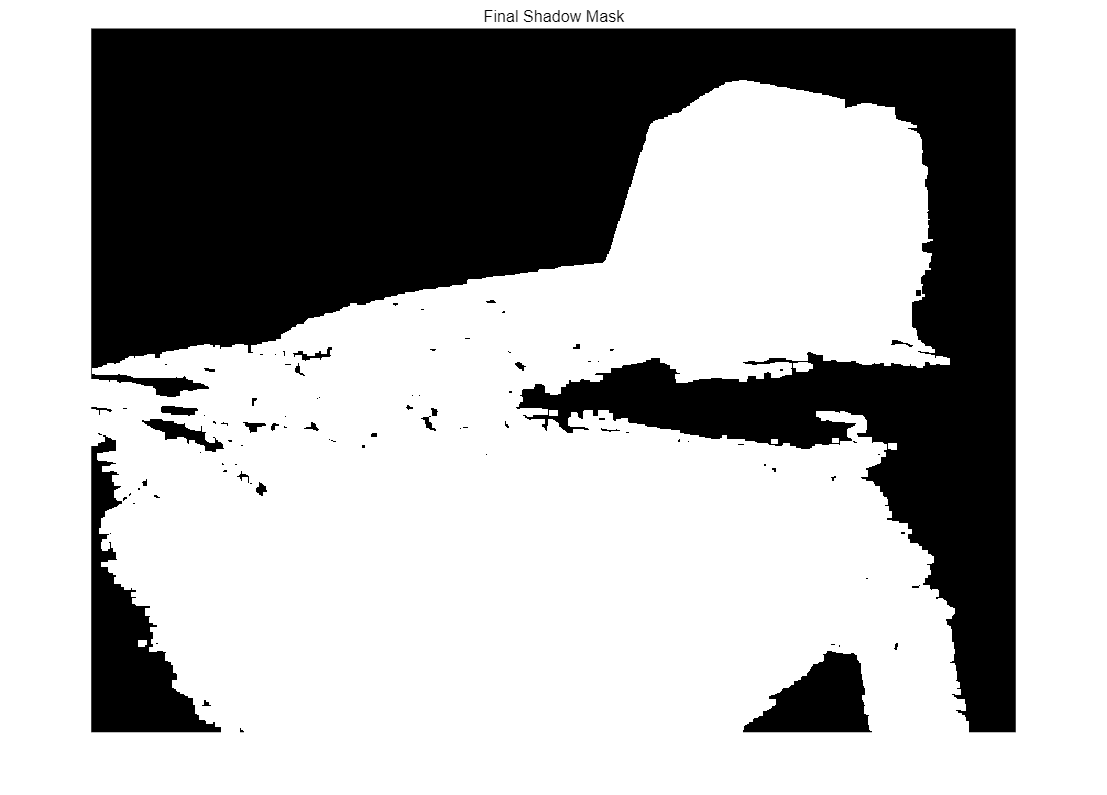

% 创建最终掩码，初始化为 0
final_mask = false(size(initial_mask));

% 区域增长逻辑
se = strel('disk', 3);  % 定义膨胀结构元素
for i = 1:length(x)
    seed = false(size(initial_mask));  % 创建种子点掩码
    seed(y(i), x(i)) = true;          % 设置基础点为种子
    region = seed;                    % 初始化区域

    % 扩张，直到区域稳定
    while true
        dilated = imdilate(region, se);    % 膨胀操作
        new_region = dilated & initial_mask; % 限制在初始掩码范围内
        if isequal(new_region, region)     % 如果区域没有变化，则退出
            break;
        end
        region = new_region;               % 更新区域
    end

    % 合并当前点的区域到最终掩码
    final_mask = final_mask | region;
end

% 显示最终掩码
figure;
imshow(final_mask, []);
title('Final Shadow Mask');